curlingImg = imread("curlingImage.jpg");
grayImg = im2gray(curlingImg);

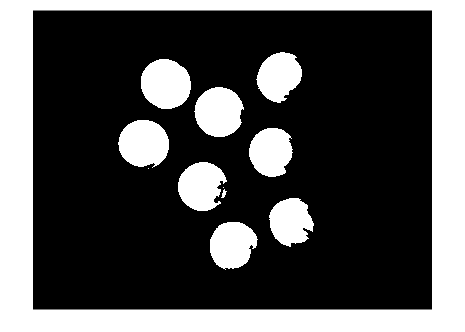

curlingMask = segmentImage(curlingImg);
imshow(curlingMask)

function [BW,maskedImage] = segmentImage(X)
%segmentImage Segment image using auto-generated code from Image Segmenter app
%  [BW,MASKEDIMAGE] = segmentImage(X) segments image X using auto-generated
%  code from the Image Segmenter app. The final segmentation is returned in
%  BW, and a masked image is returned in MASKEDIMAGE.

% Auto-generated by imageSegmenter app on 08-Jul-2023
%----------------------------------------------------

realImg = X;
X = im2gray(X);
% Threshold image with adaptive threshold
BW = im2gray(X) > 7.325000e+01;

% Invert mask
BW = imcomplement(BW);

% Close mask with default
radius = 8;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imclose(BW, se);

% Fill holes
BW = imfill(BW, 'holes');

% Close mask with default
radius = 10;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imclose(BW, se);

% Fill holes
BW = imfill(BW, 'holes');


% Create masked image.
maskedImage = realImg;
maskedImage(repmat(~BW,1,1,3)) = 0;
end



